# Final project: 

# Tracking of a maneuvering vehicle using GPS and radar data.

#  Linear and Extended Kalman filter.

## Group 6:

## • Andrei Shumeiko

## • Ayush Gupta

## • Olga Klyagina

## • Simona Nitti

## Part I.  Tracking a maneuvering vehicle using GPS data 

clc
clear
close all

### There are GPS measurements of coordinate x and y for your availability of a vehicle motion. 

load('GPS.mat'); % GPS measurements of two vehicles

### Construct a linear Kalman filter

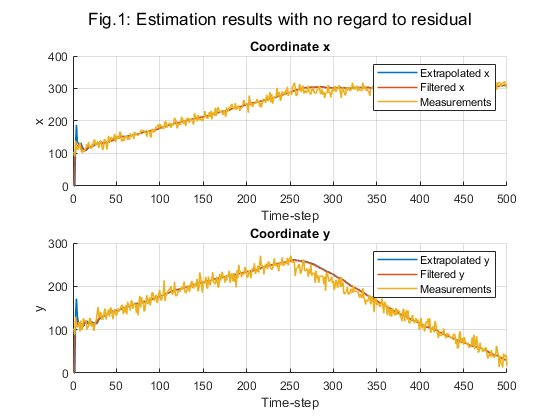

n = size(GPS,2); % Size of trajectory
T = 1;
var_a = 0.01^2;
var_eta = 10^2;

% Initial filtered estimate of state vector 
X = zeros(4,n);
P = 1e5*eye(4);

% Transition matrix
phi = eye(4)+ T*diag(ones(3,1),1);
phi(2,3)=0;

% Input matrix
G = [T^2/2 0; T 0; 0 T^2/2;0 T];

% State noise covariance matrix
Q = G*G'*var_a;

% Measurement noise covariance matrix R
R = var_eta*eye(2);

% Observation matrix
H = eye(4);
H(2:2:4,:) = [];

% Algorithm
X_pred = zeros(4,n);
for i = 2:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    
    % Filtration 
    K = P_pred*H'*inv(H*P_pred*H'+ R);
    X(:,i) = X_pred(:,i) + K*(GPS(:,i)-H*X_pred(:,i));
    P = (eye(4)-K*H)*P_pred;
end

figure
sgtitle('Fig.1: Estimation results with no regard to residual')
subplot(2,1,1)
hold on
plot(X_pred(1,:),'linewidth',1.2)
plot(X(1,:),'linewidth',1.2)
plot(GPS(1,:),'linewidth',1.2)
legend('Extrapolated x','Filtered x', 'Measurements')
grid on
xlabel('Time-step')
ylabel('x')
title('Coordinate x')

subplot(2,1,2)
hold on
plot(X_pred(3,:),'linewidth',1.2)
plot(X(3,:),'linewidth',1.2)
plot(GPS(2,:),'linewidth',1.2)
legend('Extrapolated y','Filtered y','Measurements')
grid on
xlabel('Time-step')
ylabel('y')
title('Coordinate y')

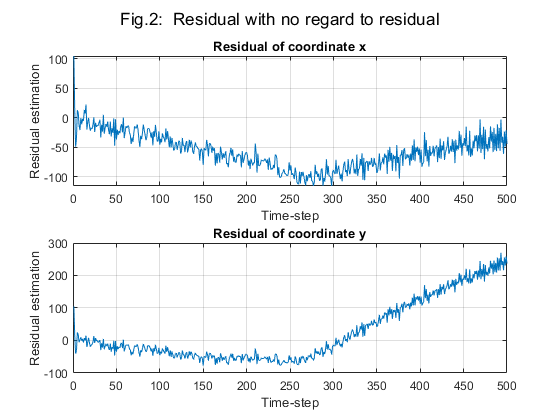

ni = zeros(2,n);
for i = 1:n
    ni(:,i) = GPS(i) - H*X(:,i);
end

figure
sgtitle('Fig.2:  Residual with no regard to residual')
subplot(2,1,1)
plot(ni(1,:)) %residual x
title('Residual of coordinate x')
grid on
xlabel('Time-step')
ylabel('Residual estimation')

subplot(2,1,2)
plot(ni(2,:)) %residual y
title('Residual of coordinate y')
grid on
xlabel('Time-step')
ylabel('Residual estimation')

We see that the maneuver is not greatly detected. How can we improve this?

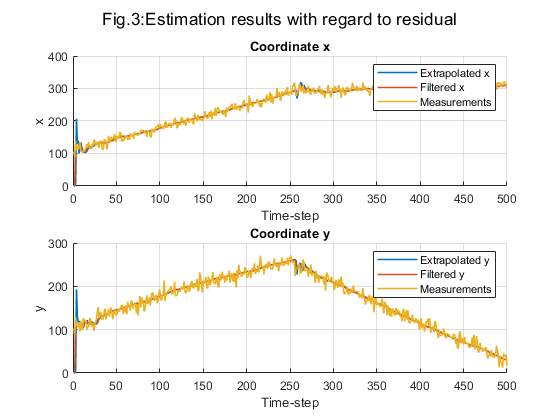

% Algorithm
X_pred = zeros(4,n);
ni = zeros(2,n);
for i = 2:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    
    % Filtration 
    K = P_pred*H'*inv(H*P_pred*H'+ R);
    ni(:,i) = (GPS(:,i)-H*X_pred(:,i));
    X(:,i) = X_pred(:,i) + K*ni(:,i);
    if abs(ni(1,i)) > 3.5*sqrt(var_eta) || abs(ni(2,i)) > 3.5*sqrt(var_eta)
        P = 1e5*eye(4);
    else
        P = (eye(4)-K*H)*P_pred;
    end
end
X_bck = X;

figure
subplot(2,1,1)
sgtitle('Fig.3:Estimation results with regard to residual')
hold on
plot(X_pred(1,:),'linewidth',1.2)
plot(X(1,:),'linewidth',1.2)
plot(GPS(1,:),'linewidth',1.2)
legend('Extrapolated x','Filtered x','Measurements')
grid on
xlabel('Time-step')
ylabel('x')
title('Coordinate x')

subplot(2,1,2)
hold on
plot(X_pred(3,:),'linewidth',1.2)
plot(X(3,:),'linewidth',1.2)
plot(GPS(2,:),'linewidth',1.2)
legend('Extrapolated y','Filtered y','Measurements')
grid on
xlabel('Time-step')
ylabel('y')
title('Coordinate y')

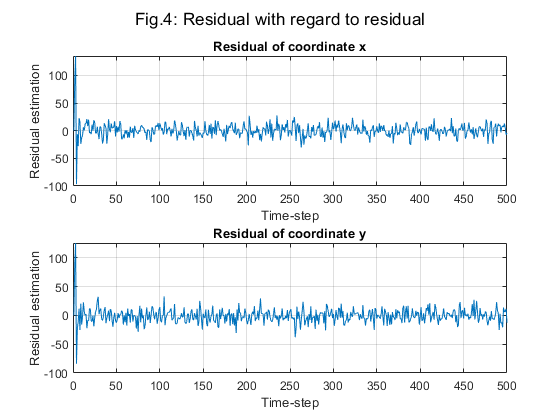

figure
sgtitle('Fig.4: Residual with regard to residual')
subplot(2,1,1)
plot(ni(1,:)) %residual x
title('Residual of coordinate x')
grid on
xlabel('Time-step')
ylabel('Residual estimation')

subplot(2,1,2)
plot(ni(2,:)) %residual y
title('Residual of coordinate y')
grid on
xlabel('Time-step')
ylabel('Residual estimation')

## Part II. Tracking a maneuvering vehicle using radar data

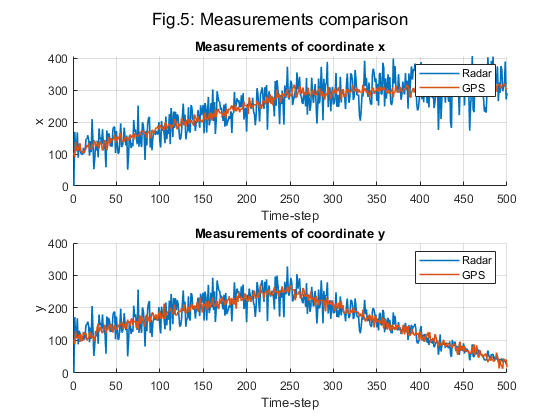

load('Radar.mat')

radar = radar';
D_meas = radar(1,:);
beta_meas = radar(2,:);
n = size(radar,2); % Size of trajectory
T = 1;
var_a = 0.01^2;
var_D = 50^2;
var_beta = 0.004^2;

% Pseudo-measurements
x_meas = D_meas.*sin(beta_meas);
y_meas = D_meas.*cos(beta_meas);
pseudo_z = [x_meas;y_meas];

figure 
sgtitle('Fig.5: Measurements comparison')
subplot(2,1,1)
hold on
plot(x_meas,'linewidth',1.2)
plot(GPS(1,:),'linewidth',1.2)
title('Measurements of coordinate x')
legend('Radar','GPS')
grid on
xlabel('Time-step')
ylabel('x')

subplot(2,1,2)
hold on
plot(y_meas,'linewidth',1.2)
plot(GPS(2,:),'linewidth',1.2)
title('Measurements of coordinate y')
legend('Radar','GPS')
grid on
xlabel('Time-step')
ylabel('y')

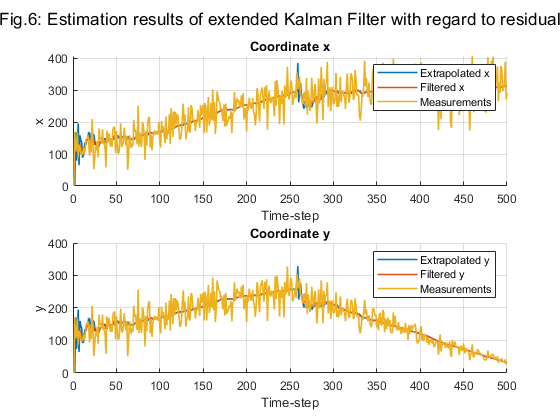

% Initial filtered estimate of state vector 
X = zeros(4,n);
X(:,2) = [D_meas(2)*sin(beta_meas(2)) 0 D_meas(2)*cos(beta_meas(2)) 0]'; % Initial filtered estimate of state vector 
P = 1e5*eye(4);

% Transition matrix
phi = eye(4)+ T*diag(ones(3,1),1);
phi(2,3)=0;

% Input matrix
G = [T^2/2 0; T 0; 0 T^2/2;0 T];

% State noise covariance matrix
Q = G*G'*var_a;

% Measurement noise covariance matrix R
R = [var_D 0
    0 var_beta];

% Observation matrix
H = eye(4);
H(2:2:4,:) = [];

% Algorithm
polar_e = zeros(2,n);
X_pred = zeros(4,n);
for i = 3:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    polar_e(1,i) = sqrt(X_pred(1,i)^2+X_pred(3,i)^2);  % extrapolated estimate of D
    polar_e(2,i) = atan(X_pred(1,i)/X_pred(3,i));      % extrapolated estimate of beta
 
    % dh/dX
    dh = zeros(2,4);
    dh(1,1) = X_pred(1,i)/sqrt(X_pred(1,i)^2 + X_pred(3,i)^2);
    dh(1,3) = X_pred(3,i)/sqrt(X_pred(1,i)^2 + X_pred(3,i)^2);
    dh(2,1) = X_pred(3,i)/(X_pred(1,i)^2 + X_pred(3,i)^2);
    dh(2,3) = -X_pred(1,i)/(X_pred(1,i)^2 + X_pred(3,i)^2);
    
    % Filtration
    K = P_pred*dh'*inv(dh*P_pred*dh'+R);
    ni(:,i) = (radar(:,i)-polar_e(:,i));
    X(:,i) = X_pred(:,i) + K*ni(:,i);
    if abs(ni(1,i)) > 3.5*sqrt(var_D) || abs(ni(2,i)) > 3.5*sqrt(var_beta)
        P = 1e5*eye(4);
    else
        P = (eye(4)-K*dh)*P_pred;
    end
    
    % Change of coordinates
    polar_f(1,i) = sqrt(X(1,i)^2+X(3,i)^2); %D
    polar_f(2,i) = atan(X(1,i)/X(3,i));     %beta
end
polar_e(:,1) = NaN(2,1);
X_pred(:,1) = NaN(4,1);


figure
subplot(2,1,1)
sgtitle(['Fig.6: Estimation results of extended Kalman Filter' ...
    ' with regard to residual'])
hold on
plot(X_pred(1,:),'linewidth',1.2)
plot(X(1,:),'linewidth',1.2)
plot(pseudo_z(1,:),'linewidth',1.2)
legend('Extrapolated x','Filtered x','Measurements')
grid on
xlabel('Time-step')
ylabel('x')
title('Coordinate x')

subplot(2,1,2)
hold on
plot(X_pred(3,:),'linewidth',1.2)
plot(X(3,:),'linewidth',1.2)
plot(pseudo_z(2,:),'linewidth',1.2)
legend('Extrapolated y','Filtered y','Measurements')
grid on
xlabel('Time-step')
ylabel('y')
title('Coordinate y')

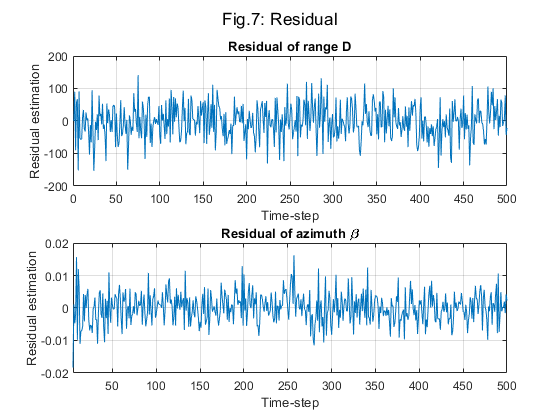

figure
sgtitle('Fig.7: Residual')
subplot(2,1,1)
plot(ni(1,:)) %residual D
title('Residual of range D')
grid on
xlabel('Time-step')
ylabel('Residual estimation')

subplot(2,1,2)
plot(ni(2,:)) %residual beta
title('Residual of azimuth \beta')
grid on
xlim([5 inf])
xlabel('Time-step')
ylabel('Residual estimation')

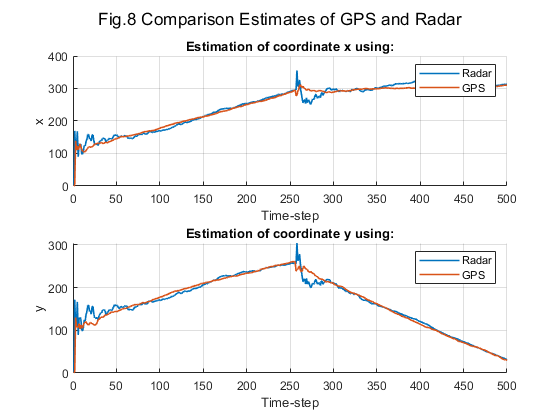

figure
subplot(2,1,1)
hold on
sgtitle('Fig.8 Comparison Estimates of GPS and Radar')
plot(X(1,:),'linewidth',1.2)
plot(X_bck(1,:),'linewidth',1.2)
legend('Radar','GPS')
grid on
xlabel('Time-step')
ylabel('x')
title('Estimation of coordinate x using:')

subplot(2,1,2)
hold on
plot(X(3,:),'linewidth',1.2)
plot(X_bck(3,:),'linewidth',1.2)
legend('Radar','GPS')
grid on
xlabel('Time-step')
ylabel('y')
title('Estimation of coordinate y using:')

## Conclusions:

The aim of our project is critically choosing which Kalman filter, linear or extended, is more efficient to track a maneuvering vehicle.

To do that, we have studied both cases separately.

In part 1, we have applied the Linear Kalman filter to the GPS measurements of coordinates x and y of the maneuvering vehicle.

In part 2, we have applied the Extended Kalman filter to the radar measurements of range D and azimuth beta of the same vehicle.

### PART I

- We have assumed that the true trajectory is described by a motion with normally distributed unbiased random acceleration with variance 𝜎𝑎^2 = 0.01^2 for both its component. This makes us identifying the transition matrix, the input matrix, and the state noise covariance matrix.

- From prior information, we know that the variance of GPS measurement noise is 10^2, for both its component, thus we can define the measurement noise covariance matrix.

- Starting with the initial filtered estimate of the state vector and initial filtration covariance matrix, we apply the Standard Kalman Filter. As we can see by the plot in Fig.1, the filtered estimates don’t adapt immediately (from time-step 250) to the strong maneuver, thus the maneuver is not greatly detected.

- To overcome this issue we have re-applied the Kalman Filter, but taking under control the filter residual (formula),  which indicates the mismatch between measurements and predictions. When its absolute value was greater than 3.5*sigma_eta, we increased the filtration error covariance matrix, setting it equal to its initial estimate.

- In this way, the residual fluctuates around zero, with amplitude 2*3.5*sigma_eta (Fig.4) and the estimations of trajectory provide a greater result.

### PART II

- In part 2, the measurements come from radar, so the measurement vector consists of range and azimuth. From a prior information, we know that the variance of measurement noise of range 𝐷 is 𝜎𝐷^2 = 50^2 (in meters), and the variance of measurement noise of azimuth 𝛽 is 𝜎𝛽^ 2 = 0.004^2 (in radians). 

- Radar measurements, converted from polar to Cartesian coordinated, have wider fluctuations compared with GPS measurements, and that makes the path look less clear(Fig.5).

- Then we have applied the Extended Kalman filter taking under control the filter residual, comparing it with 3.5𝜎𝐷 and 3.5𝜎𝛽. In Fig 6 we can observe that with the consideration of residual (formula) we get good filtered results. The residuals of 𝐷 and 𝛽 fluctuates around zero and we gets good trajectory estimations.

### Final conclusion

Comparing estimations of coordinates obtained with measurements from different sources (Fig.8), we can observe that the trajectory described using GPS data provides more reliable results, because, when the maneuver occurs (around time-step 250), it changes direction without strong fluctuations. The opposite can be said about the trajectory described using radar data; this behaviour is linked to the the error of linearization, that suddenly increases when the dynamics  of the process changes.